Consider a shallow curved beam. By tuning the curvature of the beam, the natural frequencies of the first two bending modes admit a 1:2 internal resonance.

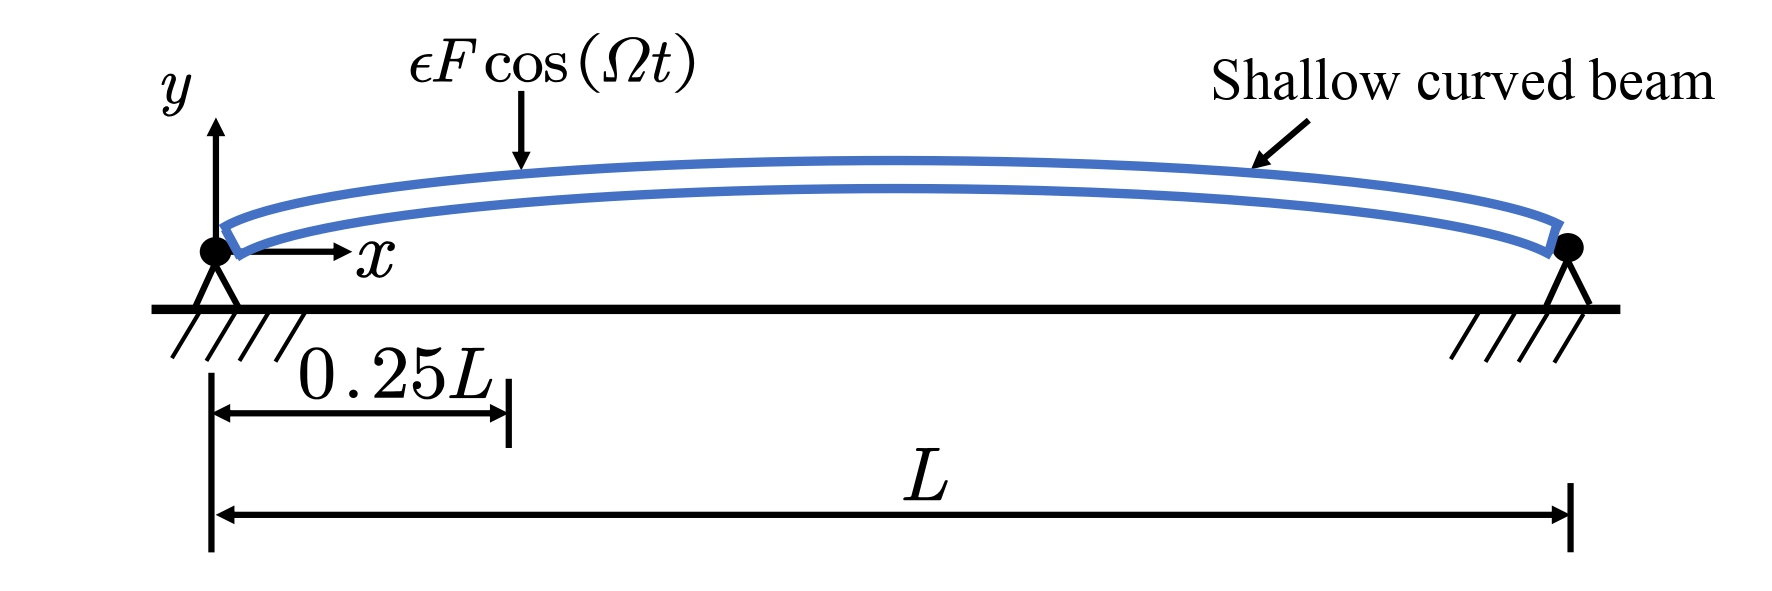

After using Galerkin method discretize the governing equation, we have


$$${M} \ddot{{q}}+{C}\dot{{q}}+ ( {K}+{H}  ) {q}+\frac{1}{2}{q}^T{BqBq} +\frac{1}{2} {q}^T{Bqd}+ {d}^T{qBq}=\epsilon{f}\cos \Omega \tau, \ \  \ 0< \epsilon \ll 1$$$


Now we analyze the 1:2 internal resonance in this beam.

### Create dynamical model

clear all;
c  = 0.01; f = 1; n = 5; Om = 39.3;
[mass,damp,stiff,fnl,fext] = build_model_semi(c,f,n);
DS = DynamicalSystem();
B = [damp mass;mass zeros(n,n)];
A = [-stiff,zeros(n,n);zeros(n,n),mass];
% F = [fnl;zeros(n,1)];
set(DS,'B',B,'A',A,'fnl_semi',fnl);
%set(DS,'B',B,'A',A,'fnl_semi',fnl);
set(DS.Options,'Emax',4,'Nmax',10);
set(DS,'fext',fext,'Omega',Om);
[V,D,W] = DS.linear_spectral_analysis();


 The first 4 eigenvalues are given as 
 -0.010000000000105 +39.478416337842127i
 -0.010000000000105 -39.478416337842127i
 -0.010000000000060 +78.958045159850968i
 -0.010000000000060 -78.958045159850968i



### SSM computation - explicit computation

S = SSM(DS);
resonant_modes = [1 2 3 4]; % choose master spectral subspace
S.choose_E(resonant_modes);

sigma_out = 0
sigma_in = 1


order = 3; % SSM expansion order
[We,Re] = S.explicit_whisker_InResonance();

### SSM computation - via SSMTool parameterization

[W_0,R_0,W_1,R_1] = ssmtool_comp(c,f,n,Om);


 The first 4 eigenvalues are given as 
 -0.010000000000105 +39.478416337842127i
 -0.010000000000105 -39.478416337842127i
 -0.010000000000060 +78.958045159850968i
 -0.010000000000060 -78.958045159850968i

sigma_out = 0
sigma_in = 1
Computing autonomous whisker at order 2
6 (near) inner resonance(s) detected at order 2
Manifold computation time at order 2 = 00:00:00
Estimated memory usage at order  2 = 1.97E-02 MB
Computing autonomous whisker at order 3
44 (near) inner resonance(s) detected at order 3
Manifold computation time at order 3 = 00:00:00
Estimated memory usage at order  3 = 9.70E-02 MB


### Comparison of SSM results 

#### Explicit solution and SSMTool solution 

disp('=======================Linear terms========================')

=======================Linear terms========================


fprintf('\n difference in terms of W1000 \n')


 difference in terms of W1000 


norm(We.W1000-full(W_0(1).coeffs(:,4)))/norm(We.W1000)

ans =      0


fprintf('\n difference in terms of W0010 \n')


 difference in terms of W0010 


norm(We.W0010-full(W_0(1).coeffs(:,2)))/norm(We.W0010)

ans =      0




disp('====================Quadratic order terms==================')

====================Quadratic order terms==================


fprintf('\n difference in terms of W2000 \n')


 difference in terms of W2000 


norm(We.W2000-full(W_0(2).coeffs(:,10)))/norm(We.W2000)

ans =      4.792652185560797e-14


fprintf('\n difference in terms of W1100 \n')


 difference in terms of W1100 


norm(We.W1100-full(W_0(2).coeffs(:,9)))/norm(We.W1100)

ans =      0


fprintf('\n difference in terms of W1010 \n')


 difference in terms of W1010 


norm(We.W1010-full(W_0(2).coeffs(:,8)))/norm(We.W1010)

ans =      1.658556225829869e-14


fprintf('\n difference in terms of W1001 \n')


 difference in terms of W1001 


norm(We.W1001-full(W_0(2).coeffs(:,7)))/norm(We.W1001)

ans =      2.099586473142306e-12


fprintf('\n difference in terms of W0020 \n')


 difference in terms of W0020 


norm(We.W0020-full(W_0(2).coeffs(:,3)))/norm(We.W0020)

ans =      8.074486863870870e-16



fprintf('\n difference in terms of gamma1 \n')


 difference in terms of gamma1 


abs(Re.r2000-full(R_0(2).coeffs(3,4)))/abs(Re.r2000)

ans =      1.943317124424652e-17


fprintf('\n difference in terms of gamma2 \n')


 difference in terms of gamma2 


abs(Re.r1001-full(R_0(2).coeffs(2,3)))/abs(Re.r1001)

ans =      3.665584744171231e-16




disp('===================Cubic order terms=======================')

===================Cubic order terms=======================


fprintf('\n difference in terms of W3000 \n')


 difference in terms of W3000 


norm(We.W3000-full(W_0(3).coeffs(:,20)))/norm(We.W3000)

ans =      1.145470203668387e-13


fprintf('\n difference in terms of W0030 \n')


 difference in terms of W0030 


norm(We.W0030-full(W_0(3).coeffs(:,4)))/norm(We.W0030)

ans =      8.285548910875373e-16


fprintf('\n difference in terms of W2100 \n')


 difference in terms of W2100 


norm(We.W2100-full(W_0(3).coeffs(:,19)))/norm(We.W2100)

ans =      1.784837981755577e-13


fprintf('\n difference in terms of W2010 \n')


 difference in terms of W2010 


norm(We.W2010-full(W_0(3).coeffs(:,18)))/norm(We.W2010)

ans =      1.212832563846677e-13


fprintf('\n difference in terms of W2001 \n')


 difference in terms of W2001 


norm(We.W2001-full(W_0(3).coeffs(:,17)))/norm(We.W2001)

ans =      4.172862617469562e-14


fprintf('\n difference in terms of W1110 \n')


 difference in terms of W1110 


norm(We.W1110-full(W_0(3).coeffs(:,15)))/norm(We.W1110)

ans =      1.122185514018136e-12


fprintf('\n difference in terms of W1020 \n')


 difference in terms of W1020 


norm(We.W1020-full(W_0(3).coeffs(:,13)))/norm(We.W1020)

ans =      1.094584779175473e-14


fprintf('\n difference in terms of W1011 \n')


 difference in terms of W1011 


norm(We.W1011-full(W_0(3).coeffs(:,12)))/norm(We.W1011)

ans =      4.483086020365721e-11


fprintf('\n difference in terms of W0120 \n')


 difference in terms of W0120 


norm(We.W0120-full(W_0(3).coeffs(:,7)))/norm(We.W0120)

ans =      6.247381765566990e-13


fprintf('\n difference in terms of W0021 \n')


 difference in terms of W0021 


norm(We.W0021-full(W_0(3).coeffs(:,3)))/norm(We.W0021)

ans =      1.044728436011404e-13



fprintf('\n difference in terms of gamma3 \n')


 difference in terms of gamma3 


abs(Re.r2100-full(R_0(3).coeffs(1,11)))/abs(Re.r2100)%11/8

ans =      5.336354669202292e-13


fprintf('\n difference in terms of gamma5 \n')


 difference in terms of gamma5 


abs(Re.r1110-full(R_0(3).coeffs(3,8)))/abs(Re.r1110)%8/6

ans =      2.365542380008294e-12


fprintf('\n difference in terms of gamma6 \n')


 difference in terms of gamma6 


abs(Re.r1011-full(R_0(3).coeffs(1,6)))/abs(Re.r1011)%6/4

ans =      5.958741103832815e-13
